load('Part_2_Data.mat');
% Calibrating Sensor
[PS_Cal PS_GOF] =fit(Position_Voltage, Position_Data,'poly1');

%Getting Uncertainty
U_PS = PS_GOF.rmse .*2;

U_PS = 1.0268

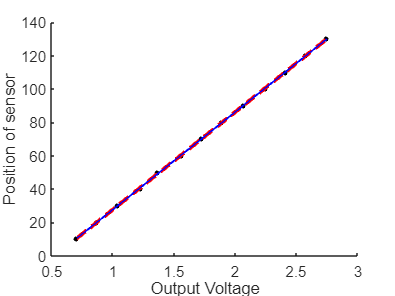


%Getting Data points from Calibration Model
PS_fit_data = feval(PS_Cal,Position_Voltage);

%Making Plot
figure
hold on
plot(Position_Voltage,Position_Data,'Marker','.','Color','k','MarkerSize',10, 'LineStyle', 'None')
%Plot of actual data

plot(Position_Voltage,PS_fit_data,'Color','b','LineWidth',1.2)
%Plot of model

plot(Position_Voltage,PS_fit_data+U_PS,'LineStyle','--','Color','r')
plot(Position_Voltage,PS_fit_data-U_PS,'LineStyle','--','Color','r')
%Plot of the prediction interval bounds

ylabel('Position of sensor')
xlabel('Output Voltage')

Ten_Percent_Range = 10*U_PS;

fprintf('The displacement range is 0mm to  %.2f mm\n', Ten_Percent_Range)

The displacement range is 0mm to  10.27 mm
